clear all
clc
syms s 
p=14.5;
numerador = [4500*p];             
d_0 = [1 0];                    
d_1 = [1, 361.2];
denominador = conv(d_0, d_1);   
fprintf('*** Función de Transferencia en lazo abierto***\n');

*** Función de Transferencia en lazo abierto***


G_p = tf(numerador, denominador)


G_p =
 
      65250
  -------------
  s^2 + 361.2 s
 
Continuous-time transfer function.
Model Properties


G_p_closedloop=feedback(G_p,1)


G_p_closedloop =
 
          65250
  ---------------------
  s^2 + 361.2 s + 65250
 
Continuous-time transfer function.
Model Properties


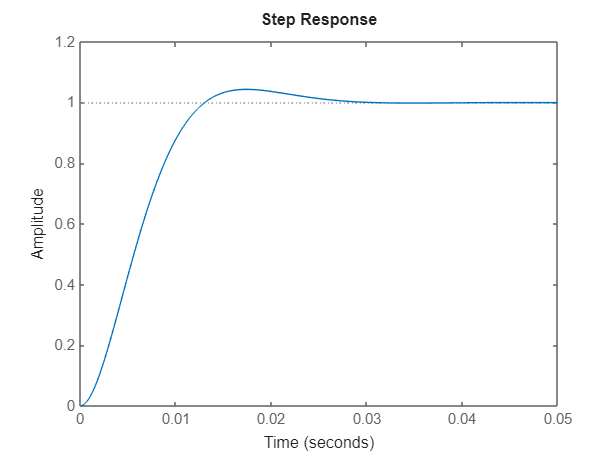

step(G_p_closedloop)
xlim([0 0.05]);
hold on

Ts=0.01648;
sys_z = c2d(tf(numerador, denominador), Ts, 'zoh')


sys_z =
 
      2.478 z + 0.4911
  ------------------------
  z^2 - 1.003 z + 0.002599
 
Sample time: 0.01648 seconds
Discrete-time transfer function.
Model Properties


sys_z_closedloop=feedback(sys_z,1)


sys_z_closedloop =
 
     2.478 z + 0.4911
  ----------------------
  z^2 + 1.476 z + 0.4937
 
Sample time: 0.01648 seconds
Discrete-time transfer function.
Model Properties


step(sys_z_closedloop)
hold on

Ts=0.01;
sys_z = c2d(tf(numerador, denominador), Ts, 'zoh')


sys_z =
 
     1.32 z + 0.4379
  ---------------------
  z^2 - 1.027 z + 0.027
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


sys_z_closedloop_1=feedback(sys_z,1)


sys_z_closedloop_1 =
 
      1.32 z + 0.4379
  -----------------------
  z^2 + 0.2929 z + 0.4649
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


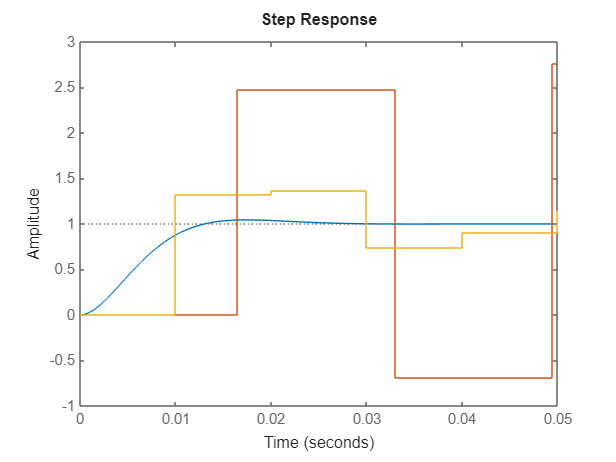

step(sys_z_closedloop_1)
hold off

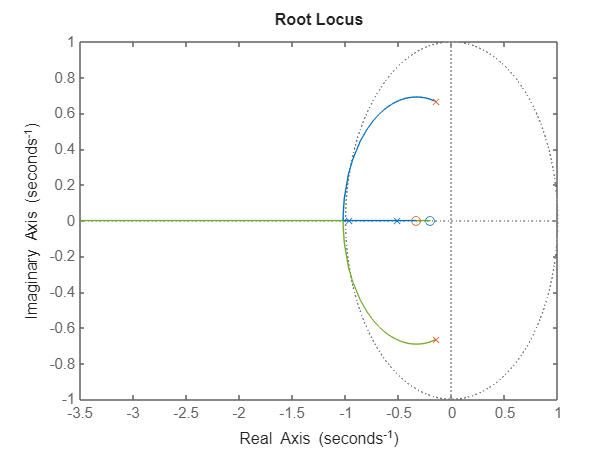


rlocus(sys_z_closedloop)

hold on
rlocus(sys_z_closedloop_1)